# OTFS EVA2 

clear all; close all;

## General settings

%% S1
Fs = 7.68e6; % Frecuencia de muestreo-Sample Rate
Ts = 1/Fs;   % Periodo de muestreo
N  = 512;    % Delay-Frecuency elements(taps) 1024
M  = 128;    % Doppler-Time elements    48
CP = 16;     % Cyclic prefix, is a copy to do posible circular convolution and make easier equalization

QAM constelations

modorder            = 4;  %constelation size

Pilot Margin 

ChanSizeDelay       = 20; % Guardian size of pilot in delay domain

ChanSizeDelay = 20

ChanSizeDoppler     = 5   % Guardian size in the doppler domain

ChanSizeDoppler = 5

pilotmargingdelay   = ChanSizeDelay;     %Delay windows axis    [0 ,A]
pilotmargingdoppler = ChanSizeDoppler*2; %Doppler windows axis, [-B,B]

Spacing or stride

DelayDataSpacing    = 3; % step size
DopplerDataSpacing  = 3;

Signal Integrity

- ¿why frames 1000 and Fdoppler 444.444?

SNR      = 60;
ppower   = 10000; %pilot power

We will do an internal doble loop one for each SNR and other for each frame. 

SNRVECT  = 0:5:30; % SNR iterator, we will test the code at diferent SNR
frames   = 1000;   % Number of frames
Fdoppler = 444.44; % 70-300 Hz, used for EVA rayleight channel. 


## RAYLEIGHT CHANNEL

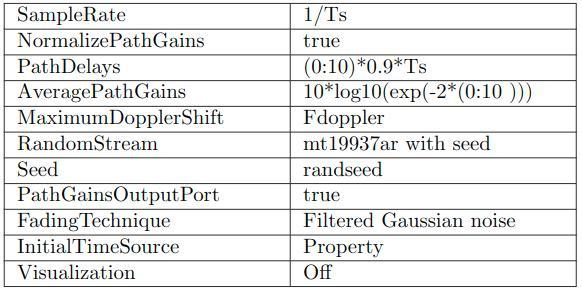

chcfg.SamplingRate    = 1/Ts;
chcfg.NormalizePathGains = 'On';  %Optional
chcfg.Seed            = 1;        %fixed seed, 0 to random seed
chcfg.NRxAnts         = 1;    
chcfg.MIMOCorrelation = 'Low';
chcfg.NormalizeTxAnts = 'On';
chcfg.DelayProfile    = 'EVA';
chcfg.DopplerFreq     = Fdoppler; %EVA 5 -70 Hz
chcfg.InitTime        = 0;
chcfg.NTerms          = 16;        %Optional
chcfg.ModelType       = 'GMEDS';   %Optional
chcfg.InitPhase       = 'Random';  %Optional

## SYMBOLS TIMING

Delay defines the symbol time. 

Tsymbol=(N+CP)*Ts;  %Time per symbol. We add cyclyc prefix
Fsymbol=1/Tsymbol;  %Simbols per second
disp(fprintf('N: %d, CP: %d, Tsymbol: %f',N,CP,Tsymbol));

N: 512, CP: 16, Tsymbol: 0.000069    33



## Stride and position

Fix possible postions given by the stride.This postions are saved in an 2D array kind of chunks of rows and its corresponding columns. Rows chunk size are MVector. We are saving the dimensional reduction grid after stride in a set of tupples. In other words we are flatting the coordenate tupples.  

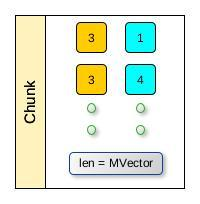

%Data stride
NVector=3:DelayDataSpacing:N-3; %stride of 3 [3,6,9,12,...,N-3]
MVector=1:DopplerDataSpacing:M; %stride of 3 [1,4,7,10,...,M  ]

%dimension after stride and flattening
dpos = zeros(numel(NVector)*numel(MVector),2); 

k=1;    %first column fixed
for i = NVector %row
    for j = MVector % column
        dpos(k,:)=[i,j]; % flatten indices in dpos
        k=k+1;
    end
    % at this point k represents chunk size
end
dataPositions=dpos; %copy of dpos
% visual aid
% first chunk
dpos(1:5+1,:)

ans =      3     1
     3     4
     3     7
     3    10
     3    13
     3    16


%second chunk
dpos(numel(MVector)+1:numel(MVector)+6,:)

ans =      6     1
     6     4
     6     7
     6    10
     6    13
     6    16


We can thinks this as flatten tupples of the reduced grid. 

## OTFS frame and placing pilot

x        = zeros(N,M); %OTFS FRAME size
pilotPos = [N/2, M/2]; % place pilot in the middle of frame
x(pilotPos(1),pilotPos(2))=sqrt(ppower); %pilot power

###         Pilot Guards

Pilot guards aka(margins) 


$$\textrm{Margin}\left\lbrack \tau_{C-\textrm{mar}} \;,\;\mu_{C+\textrm{mar}} \right\rbrack \le \textrm{Pilot}\left\lbrack \tau_C ,\mu_C \right\rbrack \le \textrm{Margin}\left\lbrack \tau_{C+\textrm{mar}} \;,\mu_{C+\textrm{mar}} \right\rbrack$$


% pilot guards tupple
pilotMargins=zeros(((1+pilotmargingdelay*2)*(2*pilotmargingdoppler+1)),2); 
k=1;
for i=pilotPos(1)-pilotmargingdelay:pilotPos(1)+pilotmargingdelay
    for j=pilotPos(2)-pilotmargingdoppler:pilotPos(2)+pilotmargingdoppler
        pilotMargins(k,:)=[i,j];% assign each tuple elment
        k=k+1;
    end
end

###         Vectorization

Vectorize stride and pilot guards. This vect will help to encode data in one single array and compare two vectors


$$\textrm{dPos}\left\lbrack 1\right\rbrack +\left(\textrm{dPos}\left\lbrack 2\right\rbrack -1\right)*N$$


-1 is for align dpos[2] to modulues 3 stride

Line projection $y=m*x+b$


$$m=N$$



$$\begin{array}{l}
x=d\left\lbrack :,2\right\rbrack \\
b=d\left\lbrack :,1\right\rbrack 
\end{array}$$


b is fixed for each M data

%Vectorizacion de posicion de datos
vecdataPositions = dataPositions(:,1)+(dataPositions(:,2)-1)*N;
%Vectorizacion de posicion de guardas (ventana alrededor piloto)
vecpilotMargins  = pilotMargins(:,1)+(pilotMargins(:,2)-1)*N;

Remove matches, as we have 1d arrays now it is simplier to remove and find

for i=1:numel(vecpilotMargins)
    index=find(vecdataPositions==vecpilotMargins(i));
    vecdataPositions(index)=[]; % remove
    dataPositions(index,:)=[];
end
%Remove pilot pos from the windows
pilotMargins(k/2,:)=[]; %remove pilot guard from pilotPos
vecpilotMargins(k/2)=[];


## TX dummy

### `   SYMPLETIC FOURIER TRANSFORM`

`SFFT = FFT cols(Delay-frec),IFFT dim rows (doppler-time)`

`Normalization sqrt (M) y (N) for FFT power`


$$\sqrt{\frac{M}{N}}\textrm{fft}\left\lbrack \left(\textrm{ifft}\left(\right.\right)\right\rbrack$$


Xdummy=sqrt(M)/sqrt(N)*fft(ifft(x,[],2),[],1); %frecuency time

###         Dummy signal OFDM to time domain

W=ones(size(Xdummy)); %Rectangular window from 
% Tx Dummy
sdummy=sqrt(N)*W.*ifft(Xdummy,[],1); %OFDM to time, multiplying by the window
stxdummy=[sdummy(end-CP+1:end,:); sdummy];  %add CP to tranmit and allow good predecitions
stxdummy=stxdummy(:)/sqrt(ppower/((N+CP)*M)); % Tx time domain normalized wih pilot power
ChanModDelayEVA=7;
stxdummy=[stxdummy ;zeros(ChanModDelayEVA,1)];


## Generacion de trama

BER=zeros(numel(SNRVECT),1);
for SNRIT=SNRVECT %Iterate over SNR values [0,5,15,20,25,30]
   errors=0;
    for k=1:frames %1000 frames

###         Data generation OTFS frame

                    Random data generation and place QAM simbols in OTFS

        %Data generatos. OTFS frame
        %modorder is the IQ order
        %Modorder*positions random bits generation over vecdataPositions space
        txbits=randi([0 1],size(vecdataPositions(1:end),1)*log2(modorder),1);
        %QAM DATA generation from the random bits
        txsymbols = qammod(txbits, modorder, 'gray', 'InputType', 'bit','UnitAveragePower', true);
        %PLACEMENT IN GRID
        x(vecdataPositions(1:end))=txsymbols;


###         Inverse simpletic fourier transform (OTFS-OFDM)

        
        X = sqrt(M)/sqrt(N)*fft(ifft(x,[],2),[],1); %OTFS to OFDM


###         Heisenberg transform (OFMD->TIME)

        s=sqrt(N)*W.*ifft(X,[],1); %OFDM to time

###        Normalize data

        stxpw_nsit=(size(dataPositions,1)+ppower);  %Frame energy
        s=s/sqrt(stxpw_nsit/(N*M));                 % Normalize to unitary power
        stx=[s(end-CP+1:end,:); s]; %Add CP
        stx=stx(:); %tx signal in time
        stx=stx/sqrt(stx'*stx/numel(stx));  %Normalize including CP
        %% Compensacion Delay Modulo de Canal- Antes de Canal
        % ChanModDelay=chan.info.ChannelFilterDelay;
        stx=[stx ;zeros(ChanModDelayEVA,1)]; % add some zeros to signal

###         Channel 

lteFadingChannel:  Filters waveform tx through the Rayleigh fading channel parameterized by model. he function returns channel output waveform rx and channel model information info

        [ChanRx,~] = lteFadingChannel(chcfg,stx); %Apply channel to stx
         %Rx+Complex Noise
        ChanRx = ChanRx+sqrt(10^(-SNR/20))*(randn(numel(ChanRx),1)+1j*randn(numel(ChanRx),1));    
        %% Delay Compensation, After channel
        ChanRx = ChanRx(ChanModDelayEVA+1:end);

        %Same with Dummy
        [ChanRxdummyEVA,infoEVA] = lteFadingChannel(chcfg,stxdummy);
        ChanRxdummy = ChanRxdummyEVA(ChanModDelayEVA+1:end);
    

##         RX

Reshape RX , to [N+CP, M]. Reshape with cyclic prefix. 

        Rx = reshape(ChanRx,N+CP,M);
        Rx = Rx(CP+1:end,:);         % Remove CP

###          Wigner Transfom

        RxOFDM=1/sqrt(N)*1./W.*fft(Rx,[],1); % Time to OFDM

###         Simpletic fourier transform (OFDM -> OTFS)

        RxOTFS=sqrt(N)/sqrt(M)*ifft(fft(RxOFDM,[],2),[],1); %

##          RX dummy process

        %RxDummy-Only pilot
        Rxdummy=reshape(ChanRxdummy,N+CP,M); % reshape 
        Rxdummy=Rxdummy(CP+1:end,:);  % Remove C
        %wigner Transform (Time to OFDM)
        RxOFDMdummy=1/sqrt(N)*W.*fft(Rxdummy,[],1);
        %Freq time to OTFS
        RxOTFSdummy=sqrt(N)/sqrt(M)*ifft(fft(RxOFDMdummy,[],2),[],1); 
        %DO zero padding in N for compensate the no-circularity

     

###         Channel estimation with pilot

        %Windows shrinking 2l+1, 2k+1
        %ChanSizeDelay are the guard size
        PSF = RxOTFS( ...
                     (-ChanSizeDelay:ChanSizeDelay)+N/2+ChanSizeDelay, ... 
                     (-ChanSizeDoppler:ChanSizeDoppler)+M/2);

        PSFideal = RxOTFSdummy((-ChanSizeDelay:ChanSizeDelay)+N/2+ChanSizeDelay, ...
                     (-ChanSizeDoppler:ChanSizeDoppler)+M/2);
        

Threshold choise/ Ideal Case

        % PSF=PSF.*(abs(PSF)>.5);    
        PSF = PSFideal;       % Usar Caso ideal
        %zero padding for N to compensate the non-circularity
        PSFOFDM = [[PSF ; zeros(N-size(PSF,1),size(PSF,2))] zeros(N,M-size(PSF,2))]; 
        PSFOFDM = sqrt(M)/sqrt(N)*fft(ifft(PSFOFDM,[],2),[],1); %OTFS-OFDM


`       Channel estimation with BEM and SIT(Done before TF to DD)`

`BEM fixes offset of the OTFS frame (Not circshift required)`

### `    E`qualization

        %Wiener with frecuency using pilot 
        % why used the conjugate here?
        iPSFOFDM  = conj(PSFOFDM)./(abs(PSFOFDM).^1+.5);
        %Rx Equalization in Time Freq. As easy as multiplication to conv
        RxEst     = RxOFDM.*iPSFOFDM;
        %Signal RxEst in freq/time to OTFS domain
        RxOTFSEst = sqrt(N)/sqrt(M)*ifft(fft(RxEst,[],2),[],1);

        % Center align the OTFS frame relative to the pilot setup.
        % Estimated pilot window in DD
        PSFEq = RxOTFSEst((-ChanSizeDelay:ChanSizeDelay)+N/2, ...
                          (-ChanSizeDoppler:ChanSizeDoppler)+M/2-ChanSizeDoppler);

        % Estimate offset to do circular shift and fix OTFS

        %Z = max value and index = argmax(PSFEQ)
        [z,indx]=max(abs(PSFEq(:)));    
           
        %Pos in Delay domain
        xi=mod(indx,ChanSizeDelay*2+1); 
        if(xi==0)
            xi=ChanSizeDelay*2+1;   %There's an edge
        end
      
        %The divison output is the frame+1 = y1
        %Rouding stuff
        yi=floor((indx-1)/(ChanSizeDelay*2+1))+1;  
        xoffset=round((1+2*ChanSizeDelay)/2)-xi; 
        yoffset=round((1+2*ChanSizeDoppler)/2)-yi+ChanSizeDoppler;

        % Power normalization
        RxOTFSEst=RxOTFSEst/z*sqrt(ppower);

        % Fit the OTFS frame using the SFFT periodicity
        RxOTFSEst=circshift(circshift(RxOTFSEst,xoffset,1),yoffset,2);
        
        %variable not used
        SFEq = RxOTFSEst((-ChanSizeDelay:ChanSizeDelay)+N/2, ...
                            (-ChanSizeDoppler:ChanSizeDoppler)+M/2);



###         Demouldation

        rxbits = qamdemod(RxOTFSEst(vecdataPositions), modorder, 'gray', 'OutputType', 'bit','UnitAveragePower', true);
        errors=sum(abs(txbits-rxbits))+errors;
    end
    BER(SNR==SNRVECT)=errors/(numel(txbits)*frames);
    SNR
end

SNR = 0

SNR = 5

SNR = 10

SNR = 15

SNR = 20

SNR = 25

SNR = 30

## Plot

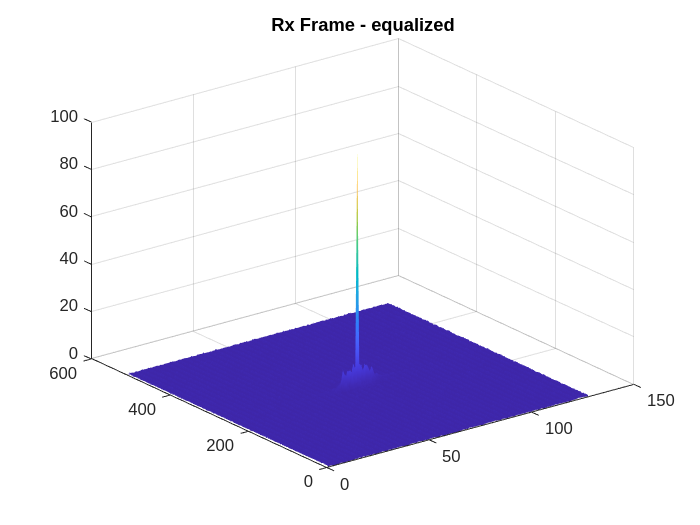

% %Trama Rx en dominio OTFS
% surf(real(RxOTFS))
% shading interp
% Rx Ecualizada en dominio OTFS (DD) 
surf(abs(RxOTFSEst)); title('Rx Frame - equalized');
shading interp

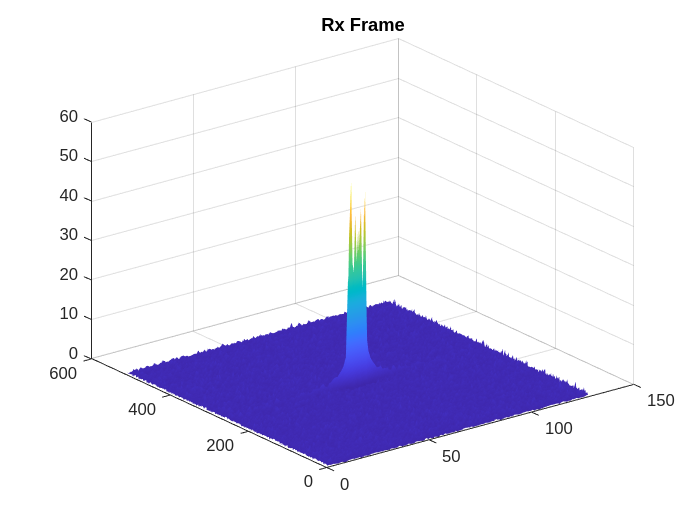

% Rx frame in DD domain
figure
surf(abs(RxOTFS)); title('Rx Frame');
shading interp

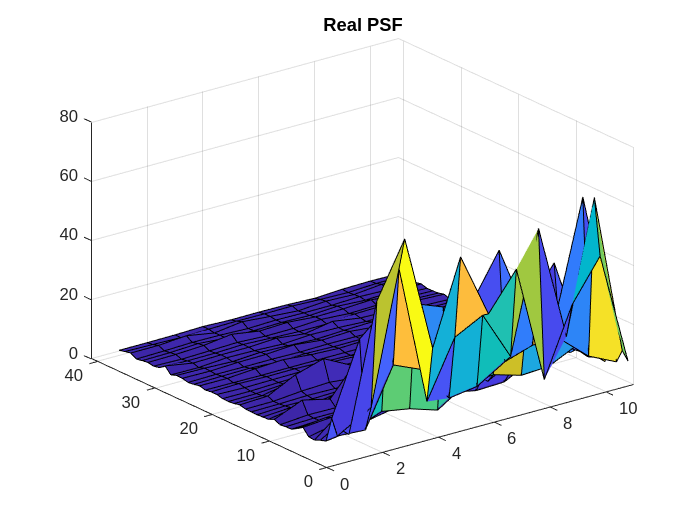

% Ventana de Piloto para estimacion en DD
figure
surf((abs(PSF))); title('Real PSF');

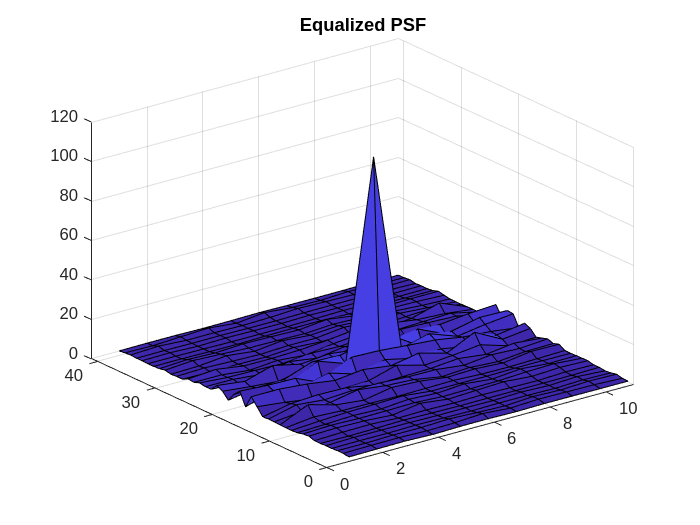

%shading interp
%Ventana de piloto estimada-Ecualizada en DD
figure
surf(abs(PSFEq)); title('Equalized PSF');

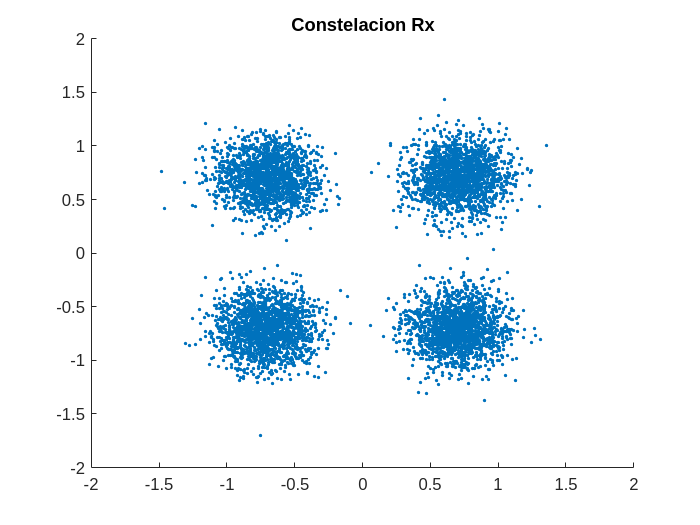

%shading interp

figure  % Grafica de puntos de constelacion
f1=scatter(real(RxOTFSEst(vecdataPositions)),imag(RxOTFSEst(vecdataPositions)),'.');
title('Constelacion Rx');
%hold on;
%scatter(real(modulator.constellation),imag(modulator.constellation),'r+');
a1=f1.get('Parent');
a1.XAxis.Limits=[-2 2];
a1.YAxis.Limits=[-2 2];


speceff=log2(modorder)*numel(vecdataPositions)/((N+CP)*M)   % Spectral efficiency

speceff = 0.2122

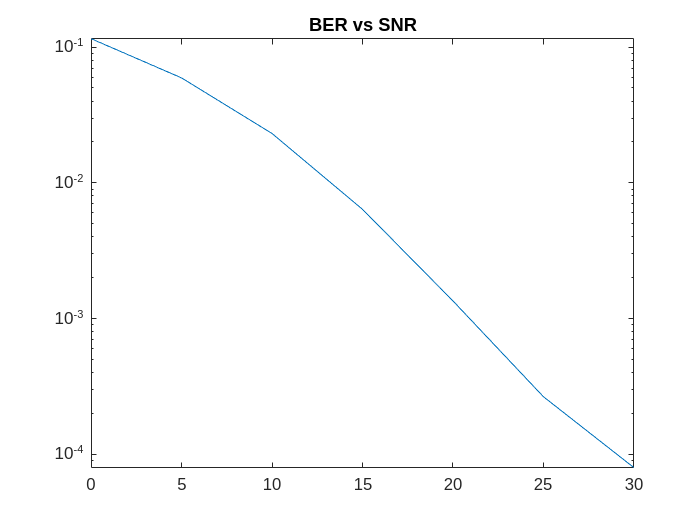

% BER VS SNR
figure
semilogy(SNRVECT,BER)
title('BER vs SNR');

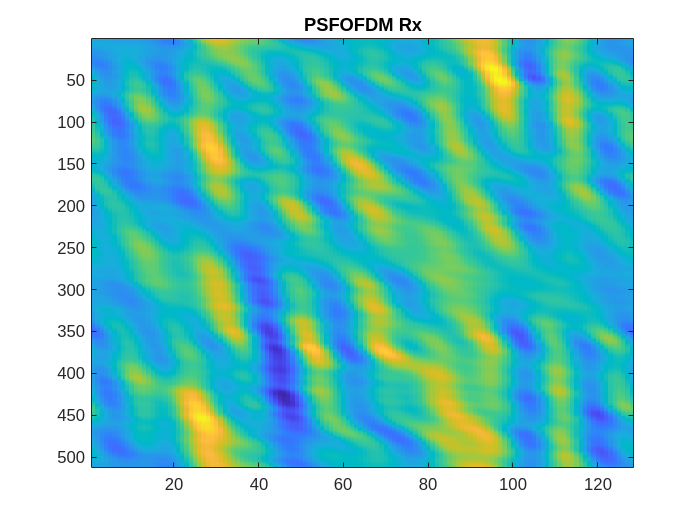

% % Matriz de Canal Estimado
% figure
% imagesc(real(PSFOfdmBem));
% title('PSFOFDM-BEM');
% Matriz de Canal Real
figure
imagesc(real(PSFOFDM));
title('PSFOFDM Rx');